experiment-6

num=[9]

num = 9

den = [0,1,4,9];
G = tf(num,den)


G =
 
        9
  -------------
  s^2 + 4 s + 9
 
Continuous-time transfer function.
Model Properties


[A,B,C,D]=tf2ss(num,den)

A =     -4    -9
     1     0


B =      1
     0


C =      0     9


D = 0

SYS =ss (A,B,C,D)


SYS =
 
  A = 
       x1  x2
   x1  -4  -9
   x2   1   0
 
  B = 
       u1
   x1   1
   x2   0
 
  C = 
       x1  x2
   y1   0   9
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.
Model Properties

[num,den] = ss2tf(A,B,C,D)

num =      0     0     9


den =     1.0000    4.0000    9.0000


G =tf (num,den)


G =
 
        9
  -------------
  s^2 + 4 s + 9
 
Continuous-time transfer function.
Model Properties


experiment-7

num=[9]

num = 9

den = [0,1,4,9];
G = tf(num,den)


G =
 
        9
  -------------
  s^2 + 4 s + 9
 
Continuous-time transfer function.
Model Properties


[A,B,C,D]=tf2ss(num,den)

A =     -4    -9
     1     0


B =      1
     0


C =      0     9


D = 0

SYS =ss (A,B,C,D)


SYS =
 
  A = 
       x1  x2
   x1  -4  -9
   x2   1   0
 
  B = 
       u1
   x1   1
   x2   0
 
  C = 
       x1  x2
   y1   0   9
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.
Model Properties

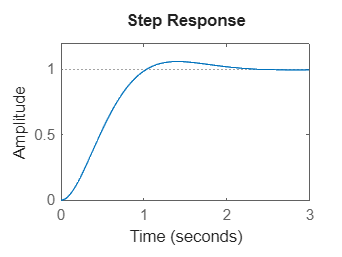

step(A,B,C,D)

e= eig (A)

e =   -2.0000 + 2.2361i
  -2.0000 - 2.2361i


deter =det(A)

deter = 9

[M,DM] =eig (A)

M =    0.9487 + 0.0000i   0.9487 + 0.0000i
  -0.2108 - 0.2357i  -0.2108 + 0.2357i


DM =   -2.0000 + 2.2361i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -2.0000 - 2.2361i


newA= inv (M)*A*M

newA =   -2.0000 + 2.2361i   0.0000 - 0.0000i
   0.0000 + 0.0000i  -2.0000 - 2.2361i


newB= inv (M)*B

newB =    0.5270 + 0.4714i
   0.5270 - 0.4714i


newC= C*M

newC =   -1.8974 - 2.1213i  -1.8974 + 2.1213i


newD= D

newD = 0

SYSnew= ss (newA,newB,newC,newD)


SYSnew =
 
  A = 
                 x1            x2
   x1      -2+2.24i   0-3.61e-16i
   x2   0+3.61e-16i      -2-2.24i
 
  B = 
                 u1
   x1  0.527+0.471i
   x2  0.527-0.471i
 
  C = 
               x1          x2
   y1  -1.9-2.12i  -1.9+2.12i
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


[new_num,new_den]= ss2tf(newA,newB,newC,newD)

new_num =    0.0000 + 0.0000i   0.0000 + 0.0000i   9.0000 + 0.0000i


new_den =    1.0000 + 0.0000i   4.0000 + 0.0000i   9.0000 - 0.0000i


Gnew=tf(new_num,new_den)


Gnew =
 
        (9+8.882e-16i)
  --------------------------
  s^2 + 4 s + (9-8.882e-16i)
 
Continuous-time transfer function.
Model Properties
